
$$\begin{array}{l}
\mathrm{Diferenta}\;\mathrm{divizata}\;\mathrm{de}\;\mathrm{ordin}\;k\;a\;\mathrm{lui}\;f\;\mathrm{cu}\;\mathrm{nodurile}\;x_0 ,x_1 ,\ldotp \ldotp \ldotp ,x_k \;f\left\lbrack x_i \right\rbrack =f\left(x_i \right)\\
f\left\lbrack x_0 ,x_1 ,\ldotp \ldotp \ldotp ,x_{k-1} ,x_k \right\rbrack =\frac{f\left\lbrack x_1 ,\ldotp \ldotp \ldotp ,x_k \right\rbrack -f\left\lbrack x_0 ,\ldotp \ldotp \ldotp ,x_{k-1} \right\rbrack }{x_k -x_0 }\\
f\left\lbrack x_i ,x_j \right\rbrack =\frac{f\left(x_i \right)-f\left(x_j \right)}{x_i -x_j }\\
f\left\lbrack x_0 ,\ldotp \ldotp \ldotp ,x_k \right\rbrack \;\mathrm{coeficientul}\;\mathrm{dominant}\;\mathrm{al}\;\left(\;L_k f\right)\left(x;x_0 ,\ldotp \ldotp \ldotp ,x_k \right)\\
f\left\lbrack x_0 ,\ldotp \ldotp \ldotp ,x_k \right\rbrack =\sum_{j=0}^k \frac{f\left(x_j \right)}{\prod_{i=0;i\not= j}^k x_j -x_i }\\
f\in C^m \left\lbrack a,b\right\rbrack \;\exists \zeta \in \left(a,b\right)\\
f\left\lbrack x_0 ,\ldotp \ldotp \ldotp ,x_k \right\rbrack =\frac{f^{\left(m\right)} \left(\zeta \right)}{m!}\\
\left(L_m f\right)\left(x\right)=f\left\lbrack x_0 \right\rbrack +f\left\lbrack x_0 ,x_1 \right\rbrack \left(x-x_0 \right)+\ldotp \ldotp \ldotp +f\left\lbrack x_0 ,\ldotp \ldotp \ldotp ,x_m \right\rbrack \left(x-x_0 \right)\ldotp \ldotp \ldotp \left(x-x_{m-1} \right)\\
\left(R_m f\right)\left(x\right)=u_m \left(x\right)f\left\lbrack x;x_0 \ldotp \ldotp \ldotp x_m \right\rbrack 
\end{array}$$
 

function td=divdiff(x,f)
lx = length(x);
f=f(:);x=x(:);
td=zeros(lx,lx);
td(:,1)=f;
for j = 2:lx
    td(1:lx-j+1,j)=diff(td(1:lx-j+2,j-1))./(x(j:lx)-x(1:lx-j+1));
end
end

x=0:5;
f=x.^3;
td=divdiff(x,f)

td =      0     1     3     1     0     0
     1     7     6     1     0     0
     8    19     9     1     0     0
    27    37    12     0     0     0
    64    61     0     0     0     0
   125     0     0     0     0     0


x=[0,pi/6,pi/4,pi/3,pi/2];
y=sin(x);
td=divdiff(x,y)

td =          0    0.9549   -0.2086   -0.1365    0.0288
    0.5000    0.7911   -0.3515   -0.0913         0
    0.7071    0.6070   -0.4471         0         0
    0.8660    0.2559         0         0         0
    1.0000         0         0         0         0


function z=Newtonpol(td,x,t)
lt=length(t);lx=length(x);
for j = 1:lt
    d=t(j)-x;
    z(j)=[1,cumprod(d(1:lx-1))]*td(1,:)';
end
end

function z=Newtonpolv2(td,x,t)
lt=length(t);
u=ones(size(t));
z=u*td(1,1);
for j = 1:lt
    u=u.*(t-x(k-1));
    z=z+u*td(1,k);
end
end

t=linspace(0,pi/2,100);

z=Newtonpol(td,x,t);
plot(x,y,'+',t,sin(t),t,z)

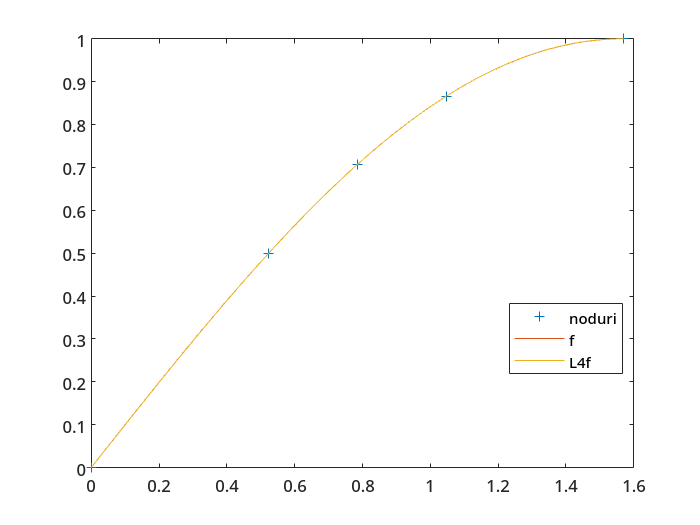

legend('noduri','f','L4f','Location','best');

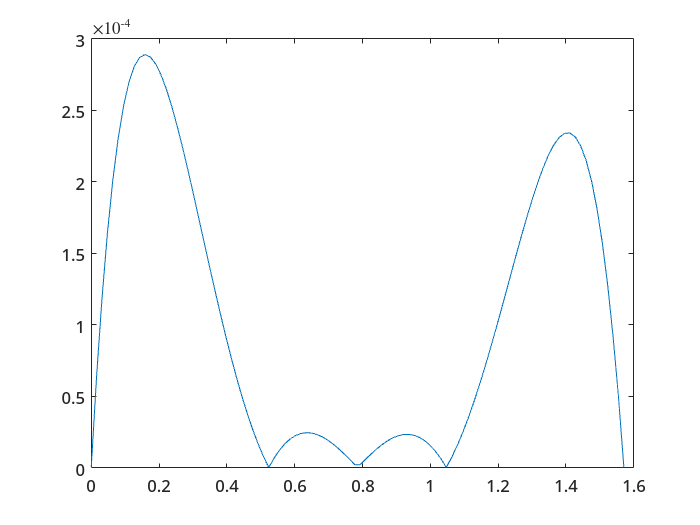

plot(t,abs(sin(t)-z));

Tema facultativa: Numar oarecare de noduri, sa se modifice valoarea functiei chiar in mijloc cu o valoare mica


$$f\left\lbrack \alpha ,\alpha ,\ldotp \ldotp \ldotp ,\alpha \right\rbrack =\lim_{x_i \to \alpha } f\left\lbrack x_1 ,\ldotp \ldotp \ldotp ,x_m \right\rbrack =\lim_{\zeta \to \alpha } \frac{f^{\left(m\right)} \left(\zeta \right)}{m!}=\frac{f^{\prime } \left(\alpha \right)}{m!}$$


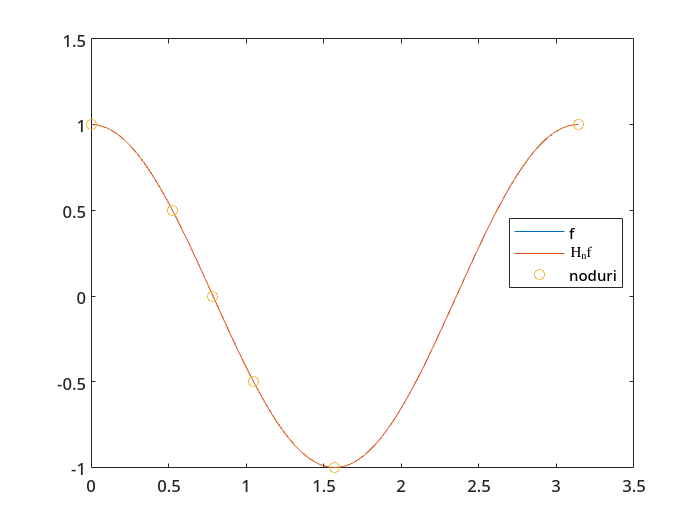

function [z,td]=divdiffdn(x,f,fd)
z=zeros(1,2*length(x));
lz=length(z);
z(1:2:lz-1)=x;
z(2:2:lz)=x;
td=zeros(lz,lz);
td(1:2:lz-1,1)=f';
td(2:2:lz,1)=f';
td(1:2:lz-1,2)=fd';
td(2:2:lz-2,2)=(diff(f)./diff(x))';
for j=3:lz
    td(1:lz-j+1,j)=diff(td(1:lz-j+2,j-1))./(z(j:lz)-z(1:lz-j+1))';
end
end

x=[0,pi/6,pi/4,pi/3,pi/2,pi];
y=cos(2*x);
yd=-2*sin(2*x);
t=pi/9;
[z,td]=divdiffdn(x,y,yd);
vp=Newtonpol(td,z,t);

t=linspace(0,pi,101);
yg=cos(2*t);
vp=Newtonpol(td,z,t);
plot(t,yg,t,vp,x,y,'o')
legend('f','H_nf','noduri','Location','best')

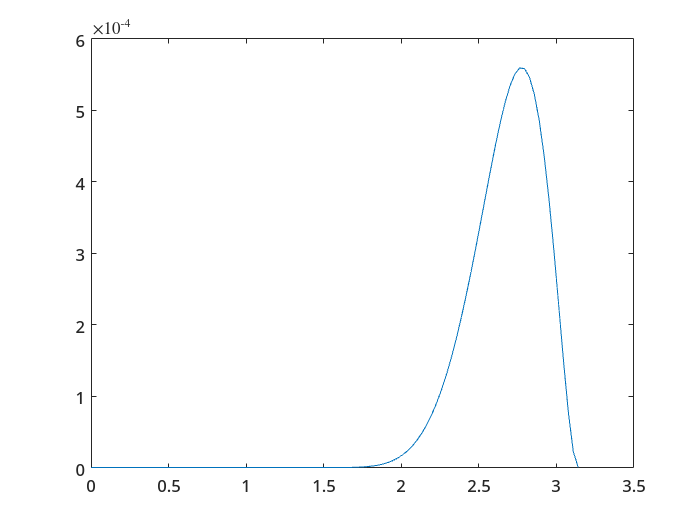

plot(t,abs(yg-vp))